# **Project#1: EngineFaultDB - Feature Extraction**

**Class: Industrial AI & Automation**

**Author: GYEONHEAL AN(21900416), GARMA JIN(21900727)**

**Date: 2024-10-22**

### **Background Introduction**

**- Necessity**

- CO, HC, and CO2, contributing to environmental problems.

- High repair costs, unexpected downtime, potential financial and safety risks.

- Solving complicating problem sensor issues, pressure problems, injector defects

**- Technical Challenges**

- Traditional Method: Manual Inspections (e.g., fuel pressure measurements, OBD-2 scanners). 

- Labor-Intensive, Expensive, and Require Expert Knowledge.

**- Solution**

- By Applying Machine Learning, Classification to Identify Types of Engine Faults.

- Classification will Help Quickly Diagnose, Resolve Engine Faults, Enabling Fast, and Efficient Repairs.

### Problem Statement

**- Objective**

- By Developing a Model that Outperforms those Implemented in Existing Journals, Accurately Identifytypes of Engine faults, Providing Greater Speedand Precision in Engine Repairs.

**- Detailed Objectives**

- Classify Datasets by Machine Learning Model Using “EngineFaultDB” Datasets.

- Understand and Analysis Datasetsthrough FeatureAnalysis.

- Improve Model Performance through FeatureExtractionand FeatureReduction/Selection

- Compare the Model Performance with Baseline Journal.

### Baseline Survey & Datasets

- **Datasets: **https://github.com/Leo-Thomas/EngineFaultDB?tab=readme-ov-file

- **Baseline Journal:** [https://ieeexplore.ieee.org/document/10311597](https://ieeexplore.ieee.org/document/10311597)

[1] Vergara, M., Ramos, L., Rivera-Campoverde, N. D., & Rivas-Echeverría, F. (2023). Enginefaultdb: a novel dataset for automotive engine fault classification and baseline results. *IEEE Access*, *11*, 126155-126171.

[2] Thomas, L. (2024). EngineFaultDB Dataset. GitHub. https://github.com/Leo-Thomas/EngineFaultDB

### **Contents**

**1. Baseline Journal Implementation**

-     Correlation Check

-     Outlier Check

-     Min-Max Scaling

-     Classification

**2. Data Preprocessing**

-     Outlier Replacement

-     Min-Max Scaling

-     Filtering

**3. Classification**

-     Logistic Regression

-     SVM

-     KNN

-     Decision Tree

**4. Result & Discussion**

## **0. Import Datasets**

clc; clear; close all;

Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
Engine_datasets = readtable(Data_location, 'VariableNamingRule', 'preserve');

% Sampling Freq
fs = 10;
Engine_datasets.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Fault'  'MAP'  'TPS'  'Force'  'Power'  'RPM'  'Consumption L/H'  'Consumption L/100KM'  'Speed'  'CO'  'HC'  'CO2'  'O2'  'Lambda'  'AFR'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


% Data Length Configuration
L0 = height(find(Engine_datasets.Fault == 0)); % Fault 0 : 16,000
L1 = height(find(Engine_datasets.Fault == 1)); % Fault 1 : 10,988
L2 = height(find(Engine_datasets.Fault == 2)); % Fault 2 : 15,000
L3 = height(find(Engine_datasets.Fault == 3)); % Fault 3 : 14,001

% Data Division (Fault0~3)
data_fault0 = Engine_datasets(Engine_datasets.Fault == 0, :);
data_fault1 = Engine_datasets(Engine_datasets.Fault == 1, :);
data_fault2 = Engine_datasets(Engine_datasets.Fault == 2, :);
data_fault3 = Engine_datasets(Engine_datasets.Fault == 3, :);
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

## 1. Baseline Journal Implementation

### 1.1. Correlation Check

To identify relationships between variables, a **Correlation Heatmap** was generated, and variables with correlations greater than **80%** were examined.

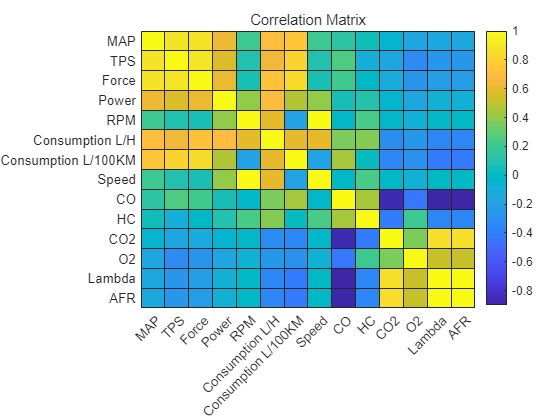

figure;
variable_names = datasets.Properties.VariableNames(2:end);
corr_matrix = corrcoef(table2array(datasets(:, 2:end)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000    0.8842    0.8801    0.6295    0.2014    0.6978    0.7396    0.2011    0.1347    0.0446   -0.0497   -0.1577   -0.1448   -0.1448
    0.8842    1.0000    0.8915    0.5826    0.0929    0.6478    0.8069    0.0927    0.2538   -0.0984   -0.1640   -0.3308   -0.2612   -0.2612
    0.8801    0.8915    1.0000    0.6214    0.0725    0.7198    0.8484    0.0719    0.2167   -0.0025   -0.1259   -0.2742   -0.2312   -0.2312
    0.6295    0.5826    0.6214    1.0000    0.4036    0.6952    0.4730    0.4059    0.0606    0.1013   -0.0413   -0.1616   -0.0788   -0.0788
    0.2014    0.0929    0.0725    0.4036    1.0000    0.6035   -0.1977    0.9969   -0.0202    0.2365   -0.0159   -0.0800   -0.0046   -0.0045
    0.6978    0.6478    0.7198    0.6952    0.6035    1.0000    0.6141    0.6033    0.3588    0.3754   -0.3134   -0.2518   -0.3476   -0.3475
    0.7396    0.8069    0.8484    0.4730   -0.1977    0.6141    1.0000   -0.1972    0.4414    0.0273   -0.3498   -0.2904   -0.4127   -0.4127
    0.2011   

% Find Variables that Correlation is higher than threshold
corr_threshold = 0.8;
high_corr = abs(corr_matrix) > corr_threshold;
high_corr = high_corr - eye(size(high_corr));
[rows, cols] = find(high_corr);

cor_idx = unique(max(rows, cols));
variable_names = datasets.Properties.VariableNames(2:end);
cor_vars = variable_names(cor_idx);

disp(['Highly Correlated Variables: ', strjoin(cor_vars, ', ')]);

Highly Correlated Variables: TPS, Force, Consumption L/100KM, Speed, CO2, Lambda, AFR


### 1.2. Box Plot

**Box plot** is a visual tool that displays the distribution of data, showing the **minimum, first quartile, median, third quartile, and maximum**, which helps visualize the spread and detect outliers in the dataset.

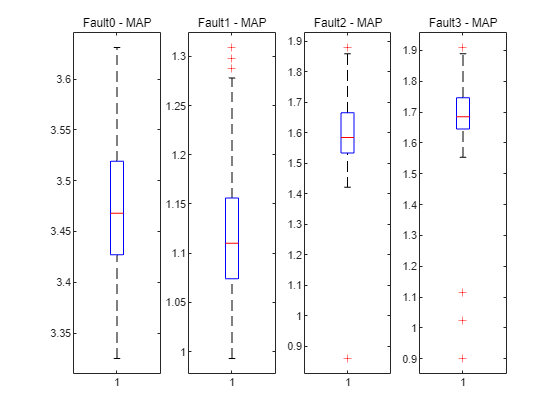

figure;
subplot(1,4,1);
boxplot(data_fault0.MAP(1:1000))
title("Fault0 - MAP")
subplot(1,4,2);
boxplot(data_fault1.MAP(1:1000))
title("Fault1 - MAP")
subplot(1,4,3);
boxplot(data_fault2.MAP(1:1000))
title("Fault2 - MAP")
subplot(1,4,4);
boxplot(data_fault3.MAP(1:1000))
title("Fault3 - MAP")

### 1.3. Scaling : Min-Max Scaling

Since the variables in the given datasets are measured in different units (e.g., rpm, %, Pa), Min-Max Scaling was applied to normalize their ranges between 0 and 1.

% Scaling Datasets Using Min-Max Scaling
scaled_datasets = datasets;

for i = 2:width(datasets)

    X_min = min(datasets{:, i});
    X_max = max(datasets{:, i});
    
    %paper equation
    scaled_datasets{:, i} = (datasets{:, i} - X_min) / (X_max - X_min);
end

### 1.4. Classification

Before training, the data was split into training and test sets in an 8:2 ratio.

% Train/Test Datasets Division
label_data = scaled_datasets.Fault;
input_data = scaled_datasets(:, 2:end);

total_size = height(scaled_datasets);
idx_rand = randperm(total_size);

train_n = round(total_size * 0.8);
test_n = round(total_size * 0.2);

train_index = idx_rand(1:train_n);
test_index = idx_rand(train_n+1:train_n+test_n);

X_train = input_data(train_index, :);
Y_train = label_data(train_index);

X_test = input_data(test_index, :);
Y_test = label_data(test_index);

#### 1.4.1. Logistic Regression

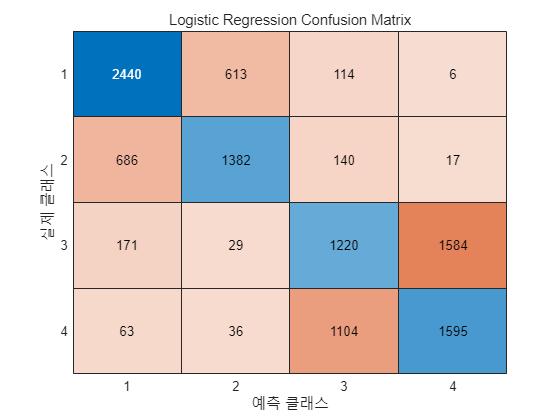

Mdl_LR = fitcecoc(X_train, Y_train, 'Learners', templateLinear('Learner', 'logistic'));
Ypred = predict(Mdl_LR, X_test);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('Logistic Regression Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.5926

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.5916

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.5921

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score)

mean_f1_score = 0.5902

#### 1.4.2. Support Vector Classification (SVC)

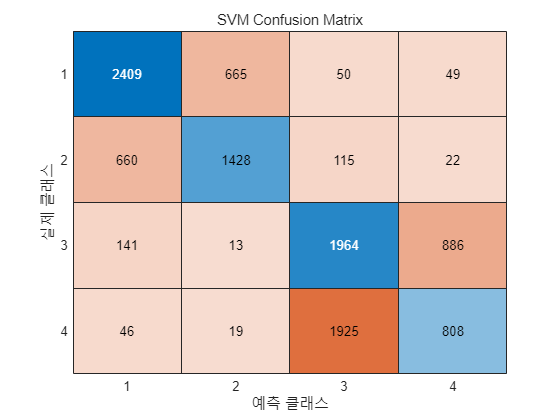

MDL_SVM = fitcecoc(X_train, Y_train, 'ClassNames',{'0','1','2','3'});
Ypred = predict(MDL_SVM, X_test);
Ypred = cellfun(@str2double, Ypred);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('SVM Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.5901

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.5859

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.5885

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score)

mean_f1_score = 0.5792

#### 1.4.3. KNN

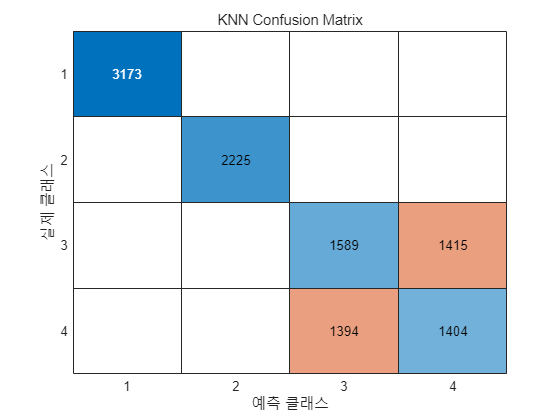

MDL_KNN = fitcknn(X_train, Y_train);
Ypred = predict(MDL_KNN, X_test);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('KNN Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.7492

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.7577

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.7577

#### 1.4.4. Decision TREE

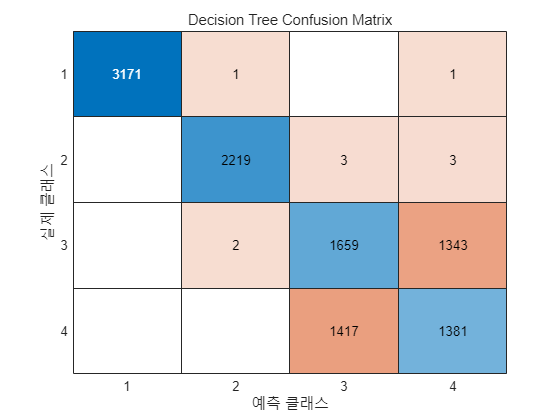

MDL_TREE = fitctree(X_train, Y_train);
Ypred = predict(MDL_TREE, X_test);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('Decision Tree Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.7527

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.7606

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.7609

Compared to the Baseline Journal below, it was confirmed that the results are similar.

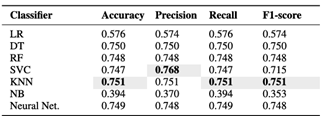

## **2. Data Preprocessing**

To improve model performance beyond the Baseline Journal and to clearly classify fault types, the focus was placed on Data Preprocessing. 

First, Raw Signal Analysis was performed.

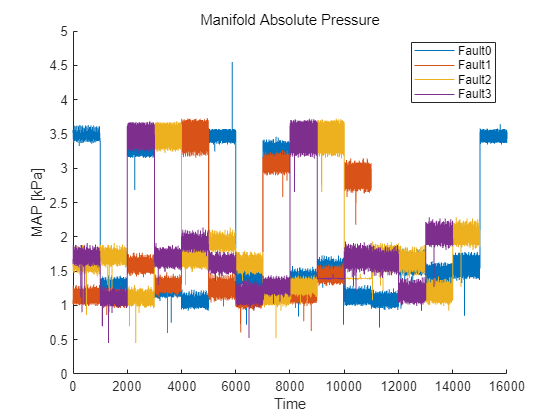

figure;
hold on;
plot((1:L0), Engine_datasets(Engine_datasets.Fault == 0, :).MAP);
plot((1:L1), Engine_datasets(Engine_datasets.Fault == 1, :).MAP);
plot((1:L2), Engine_datasets(Engine_datasets.Fault == 2, :).MAP);
plot((1:L3), Engine_datasets(Engine_datasets.Fault == 3, :).MAP);
legend('Fault0', 'Fault1', 'Fault2', 'Fault3')
xlabel("Time");
ylabel("MAP [kPa]");
title("Manifold Absolute Pressure");

Upon examining the EngineFaultDB dataset, it was found that 1000 data points were measured per case. The dataset contains 16,000 samples for Fault0, 10,998 for Fault1, 15,000 for Fault2, and 14,001 for Fault3. 

There are a total of 14 variables, including pressure, speed, RPM, CO concentration %, and others measured in various units. 

The raw data collected through sensors contained outliers.

% Data Division (Fault0~3)
data_fault0 = Engine_datasets(Engine_datasets.Fault == 0, :);
data_fault1 = Engine_datasets(Engine_datasets.Fault == 1, :);
data_fault2 = Engine_datasets(Engine_datasets.Fault == 2, :);
data_fault3 = Engine_datasets(Engine_datasets.Fault == 3, :);
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

### 2.1. Outlier Check & Replacement

The data revealed a significant presence of outliers during the sensor data acquisition process. To replace these outliers, the **Linear Interpolation** method was used.

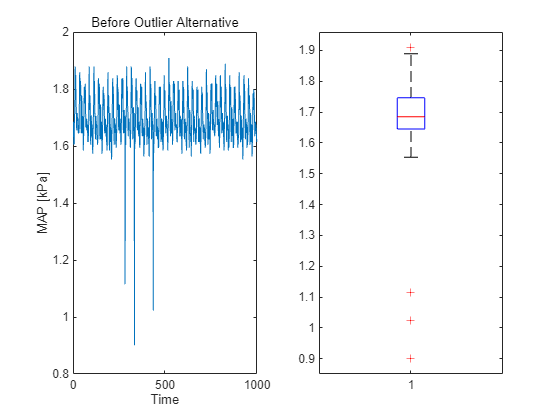

figure;
subplot(1,2,1);
plot(data_fault3.MAP(1:1000,:))
xlabel("Time");
ylabel("MAP [kPa]");
title("Before Outlier Alternative");
subplot(1,2,2);
boxplot(data_fault3.MAP(1:1000,:))

% Outlier Replacement - Linear interpolation
data_faults = {data_fault0, data_fault1, data_fault2, data_fault3};

for i = 1:4
    for t = 1000:1000:10000
        outliers = isoutlier(data_faults{i}(t-999:t, :));
        data_faults{i}(t-999:t, :) = filloutliers(data_faults{i}(t-999:t, :), 'linear');
    end
end

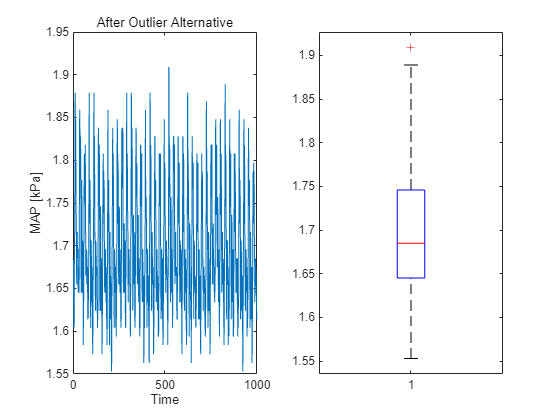

%% Update
data_fault0 = data_faults{1};
data_fault1 = data_faults{2};
data_fault2 = data_faults{3};
data_fault3 = data_faults{4};
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

figure;
subplot(1,2,1);
plot(data_fault3.MAP(1:1000,:))
xlabel("Time");
ylabel("MAP [kPa]");
title("After Outlier Alternative");
subplot(1,2,2);
boxplot(data_fault3.MAP(1:1000,:))

Compared to the previous plot, it is evident that the number of outliers has significantly decreased.

### 2.2. Correlation Check for each Fault cases

In the Baseline Journal, the correlation between all datasets from Fault0 to Fault3 was compared. However, in this process, the focus is on: 

- **Identifying which variables have high correlation within each individual fault dataset** (i.e., Fault0, Fault1, Fault2, Fault3).

- **Analyzing how similar the correlation heatmaps are across different fault datasets**, to assess the degree of consistency or variation in variable relationships between different fault types.

data_fault0 : Normal

data_fault1 : Rich Mixture 

- High Fuel Pressure

- Incorrect Sensor Performance

- Defective Injector

- Faulty Pressure Regulator

- Clogged Air Filter

- Clogged Fuel return line

data_fault2 : Lean Mixture

- Incorrect Sensor Performance

- Low fuel Pressure

- Defective Injector

- Faulty Pressure Regulator

data_fault3 : Low Voltage

- Worn Spark plugs

- Faulty Ignition Cables

- Defective Coils

- Faulty sensor wiring

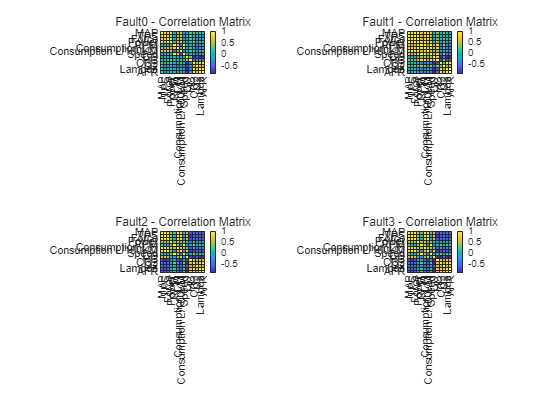

figure;
subplot(2,2,1);
variable_names = data_fault0.Properties.VariableNames(2:end);
corr_matrix_0 = corrcoef(table2array(data_fault0(:, 2:end)));
heatmap(corr_matrix_0, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault0 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,2);
variable_names = data_fault1.Properties.VariableNames(2:end);
corr_matrix_1 = corrcoef(table2array(data_fault1(:, 2:end)));
heatmap(corr_matrix_1, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault1 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,3);
variable_names = data_fault2.Properties.VariableNames(2:end);
corr_matrix_2 = corrcoef(table2array(data_fault2(:, 2:end)));
heatmap(corr_matrix_2, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault2 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,4);
variable_names = data_fault3.Properties.VariableNames(2:end);
corr_matrix_3 = corrcoef(table2array(data_fault3(:, 2:end)));
heatmap(corr_matrix_3, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault3 - Correlation Matrix', 'Colormap', parula);

After checking the correlation for each fault, it was observed that the correlation matrix for **Fault2** and **Fault3** is highly similar. 

This suggests that during the classification process, distinguishing between **Fault2** and **Fault3** may be more challenging due to the strong similarity in the relationships between variables for these two faults.

### 2.3. Min-Max Scaling

As in the previous Baseline Journal, **Min-Max Scaling** was applied. This method normalizes the data by scaling the values of each variable to a range between 0 and 1, ensuring consistency across different units for better comparison and analysis during the modeling process.

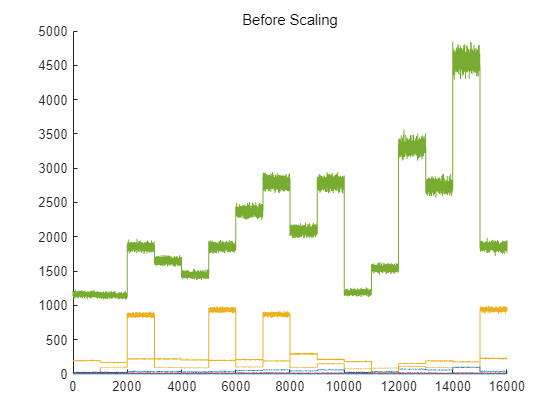

figure;
hold on;
for i = 2:width(data_fault0)
    plot(table2array(data_fault0(:, i)));
end
hold off;
title('Before Scaling')

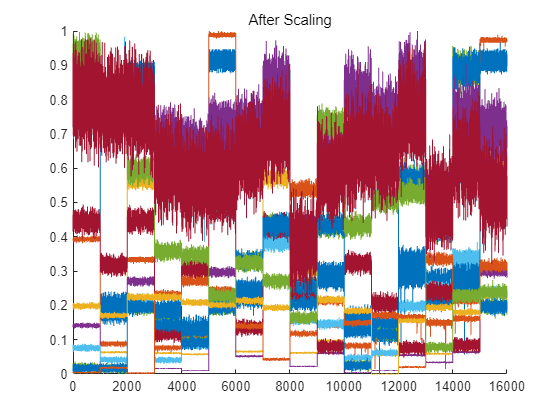

% Min-Max Scaling
variables = datasets.Properties.VariableNames(2:end);
for i = 1:length(variables)
    datasets.(variables{i}) = normalize(datasets.(variables{i}), 'range');
end

% Update
data_fault0 = datasets(datasets.Fault == 0, :);
data_fault1 = datasets(datasets.Fault == 1, :);
data_fault2 = datasets(datasets.Fault == 2, :);
data_fault3 = datasets(datasets.Fault == 3, :);

figure;
hold on;
for i = 2:width(data_fault0)
    plot(table2array(data_fault0(:, i)));
end
hold off;
title('After Scaling')

### 2.4. Data Cutoff

The amount of data for **Fault0 to Fault3** differs, and it was found that datasets beyond the 10,000th point contain missing values. Therefore, only the data up to the **10,000th sample** was used to ensure consistency across all datasets and avoid the issues caused by missing values.

data_fault0 = datasets(1:10000,:);
data_fault1 = datasets(L0+1:L0+10000, :);
data_fault2 = datasets(L0+L1+1:L0+L1+10000, :);
data_fault3 = datasets(L0+L1+L2+1:L0+L1+L2+10000, :);
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

### 2.5. Noise Reduction - Low pass filter

In this dataset, the key focus is not on observing changes over time (as in typical time series data), but rather on analyzing the distribution of variables within each case. 

However, due to significant noise in the acquired data, the variables are distributed with a large standard deviation, making it difficult to train the model effectively.

To address this issue, a **Butterworth Lowpass Filter** was applied, which helps reduce the standard deviation of the data by smoothing out high-frequency noise. This filtering process allows the underlying distribution characteristics of the data to become clearer, enhancing the model's ability to learn from the data.

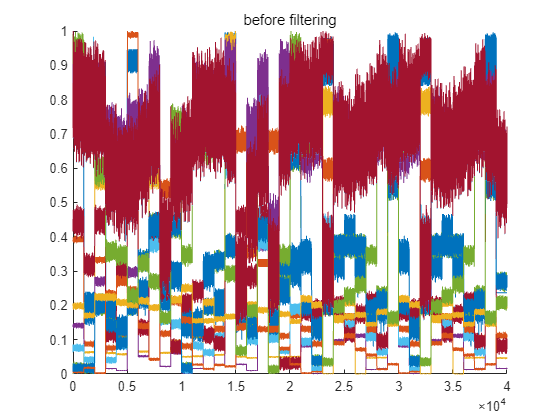

figure;
hold on;
for i = 2:width(datasets)
    plot(table2array(datasets(:,i)))
end
hold off;
title('before filtering')

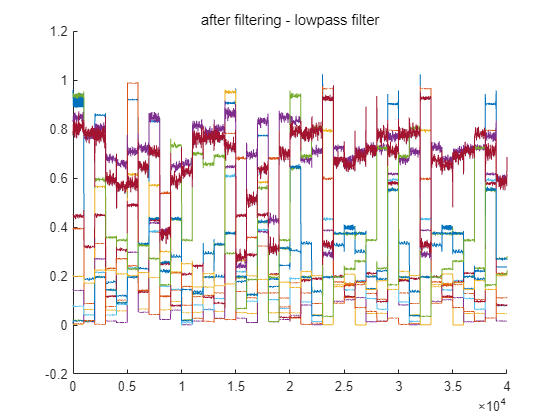

% Filter Structure
filtered_datasets = table2array(datasets);

d1 = designfilt("lowpassiir",FilterOrder=12, ...
    HalfPowerFrequency=0.05,DesignMethod="butter");

filtered_ = filtered_datasets;

% Apply Butterworth Lowpass Filter
T = 1000;
for k = 2:width(filtered_datasets)
    for i = T:T:length(filtered_datasets)
        filtered_(i-999:i, k) = filtfilt(d1,filtered_datasets(i-999:i, k));
    end
end
filtered_=array2table(filtered_);
filtered_.Properties.VariableNames = datasets.Properties.VariableNames;

figure;
hold on;
for i = 2:width(filtered_)
    plot(table2array(filtered_(:,i)))
end
hold off;
title('after filtering - lowpass filter')

Compared to the previous plot, after applying the **Butterworth Lowpass Filter**, the standard deviation of the data was significantly reduced, allowing the distribution characteristics of the data to be more clearly defined. This smoothing process helped eliminate high-frequency noise, making the patterns in the variables easier to interpret and thus improving the data's suitability for training.

%update
data_fault0 = filtered_(1:10000, :);
data_fault1 = filtered_(10001:20000, :);
data_fault2 = filtered_(20001:30000, :);
data_fault3 = filtered_(30001:40000, :);

## 3. Classification

#### Train/Test Data Split

The **train** and **test datasets** were randomly split in an 80% : 20% ratio. This ensures that 80% of the data is used for model training and 20% is reserved for testing the model's performance on unseen data. 

data_faults = [data_fault0; data_fault1; data_fault2; data_fault3];
label_data = data_faults.Fault;
input_data = data_faults(:, 2:end);

total_size = height(data_faults);
idx_rand = randperm(total_size);

train_n = total_size * 0.8;
test_n = total_size * 0.2;

train_index = idx_rand(1:train_n);
test_index = idx_rand(train_n+1:train_n+test_n);

X_train = input_data(train_index, :);
Y_train = label_data(train_index);

X_test = input_data(test_index, :);
Y_test = label_data(test_index);

### 3.1. Logistic Regression

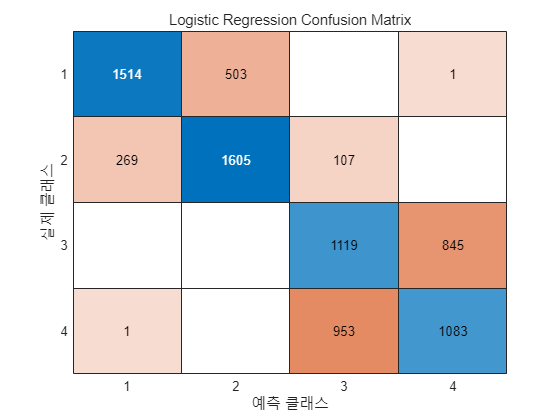

Mdl_LR = fitcecoc(X_train, Y_train, 'Learners', templateLinear('Learner', 'logistic'));
Ypred = predict(Mdl_LR, X_test);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('Logistic Regression Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.6651

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.6655

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.6713

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score)

mean_f1_score = 0.6669

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score, 'omitnan')

mean_f1_score = 0.6669

### 3.2. Support Vector Classification (SVC)

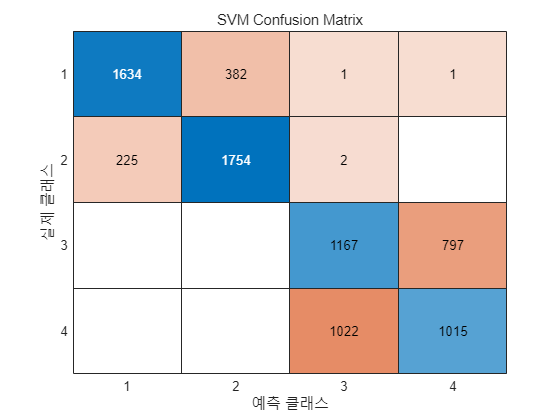

MDL_SVM = fitcecoc(X_train, Y_train, 'ClassNames',{'0','1','2','3'});
Ypred = predict(MDL_SVM, X_test);
Ypred = cellfun(@str2double, Ypred);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('SVM Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.6963

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.6969

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.6981

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score)

mean_f1_score = 0.6960

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score, 'omitnan')

mean_f1_score = 0.6960

#### 3.3. KNN

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.014312 |      2.0795 |    0.014312 |    0.014312 |            3 |    cityblock |         true |
|    2 | Accept |     0.57597 |      22.055 |    0.014312 |    0.044392 |         5914 |    cityblock |         true |
|    3 | Accept |     0.16478 |      3.4518 |    0.014312 |    0.032083 |          107 |    minkowski |         true |
|    4 | Accept |     0.66059 |      44.458 |    0.014312 |    0.038003 |        14542 |    minkowski |        false |
|    5 | Accept |    0.022156 |      3.2977 |   

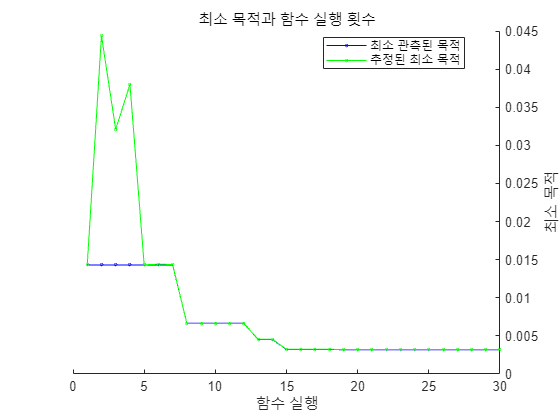

MDL_KNN = fitcknn(X_train, Y_train, ...
    'OptimizeHyperparameters', 'auto', ...   
    'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName', 'expected-improvement-plus'));

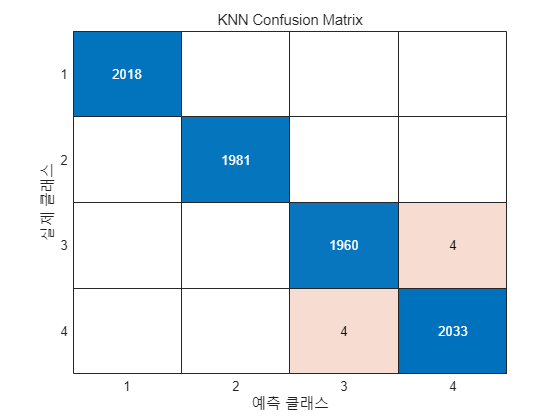

Ypred = predict(MDL_KNN, X_test);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('KNN Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.9990

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.9990

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.9990

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score, 'omitnan')

mean_f1_score = 0.9990

### 3.4. Decision Tree

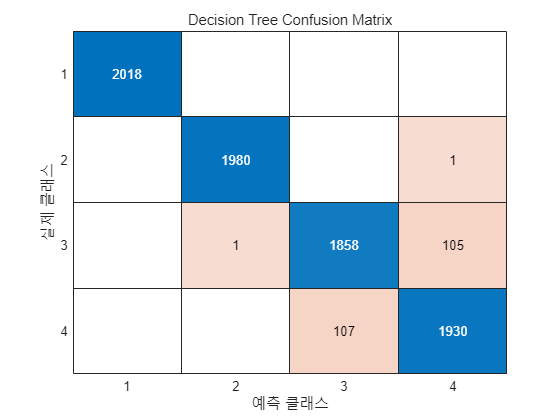

MDL_TREE = fitctree(X_train, Y_train);
Ypred = predict(MDL_TREE, X_test);

figure;
confMat = confusionmat(Y_test, Ypred);
confusionchart(confMat);
title('Decision Tree Confusion Matrix');

accuracy = sum(diag(confMat)) / sum(confMat(:))

accuracy = 0.9732

precision = diag(confMat) ./ sum(confMat, 2);
mean_precision = mean(precision)

mean_precision = 0.9732

recall = diag(confMat) ./ sum(confMat, 1)';
mean_recall = mean(recall)

mean_recall = 0.9732

f1_score = 2 * (precision .* recall) ./ (precision + recall);
mean_f1_score = mean(f1_score, 'omitnan')

mean_f1_score = 0.9732

## 4. Result & Discussion

The comparison between the model performance before and after data preprocessing is as follows.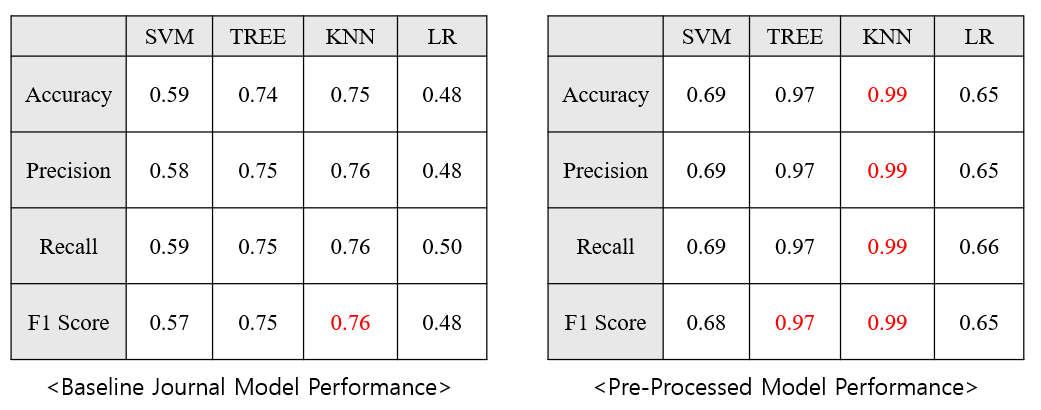

After applying **Data Preprocessing**, the model's performance, as measured by the F1 Score, improved from **76% to 99%**, increasing classification accuracy by 23%. 

While both **SVM** and **Logistic Regression** also showed performance improvements, the significant gains in **Decision Tree** and **KNN** can be attributed to the following reasons:

- The **KNN** model, being distance-based, benefited from having variables with similar patterns (e.g., **MAP, TPS, CO**), which allowed it to classify closely related data points more effectively.

- The **Decision Tree** model, with its clear classification rules, was well-suited to the **EngineFaultDB** dataset, which contains multiple input variables, making it an ideal model for this dataset.

- Although both **KNN** and **Decision Tree** are typically vulnerable to noise, the application of the **Butterworth Low-Pass filter** helped mitigate this issue, leading to the significant performance improvement observed.